## 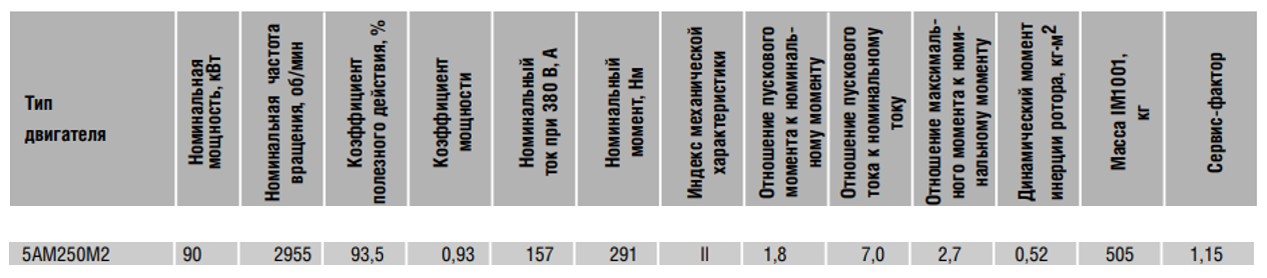

## ЗАДАНИЕ 1

А) Рассчитаем параметры схемы замещения АД

Pn = 90*10^3; % номинальная мощность
nn = 2955; % номинальная частота вращения (об/мин)
kpd = 93.5/100; % коэффициент полезного действия
cosfi = 0.93; % коэффициент мощности
Un = 380/sqrt(3); % фазное напряжение питания
In = 157; % линейный или фазный ток 
Mn = 291; % номинальный момент нагрузки
ks = 1.8; % кратность пускового момента ks =Ms/Mn
ki = 7; % кратность пускового тока ki =Is/In
lyambda = 2.7; % кратность максимального момента λ=Mm/Mn

m = 3; % число фаз
f = 50; % частота сети
zp = 1; % число пар полюсов

n1 = 60*f/zp % частота вращения магнитного поля статора(скорость циклического изменения магнитного потока статора, называется синхронной скоростью двигателя)

n1 = 3000

sn = (n1-nn)/n1 % величина номинального скольжения

sn = 0.0150

N = 3000; % синхронная частота вращения (об/мин)
J = 0.52; %
mass = 505; %
service_factor = 1.15; %

% Параметры схемы замещения
w1 = 2*pi*f  % Скорость вращения поля

w1 = 314.1593


%------
Rs = (Un*In*cosfi-Mn*w1/m/zp)/In^2

Rs = 0.0633

Rr0 = m*zp*Un^2*sn/w1/Mn

Rr0 = 0.0237

%------

mu_m = @(r2_) mu_m_calc(r2_,Rs,sn,lyambda,In,cosfi,Un,m,zp,w1,Mn);
Rr = fzero(mu_m,Rr0)

Rr = 0.0212


a = Rs/Rr

a = 2.9803

A = 1-2*a*sn*(lyambda-1)

A = 0.8480

s_m = sn*(lyambda+sqrt(lyambda^2-A))/A

s_m = 0.0927

x_ks = sqrt((Rr/s_m)^2-Rs^2)

x_ks = 0.2203

b = x_ks/((Rs+Rr/sn)^2+x_ks^2)

b = 0.0985

x_m = 1/((In*sqrt(1-cosfi^2))/Un-b)

x_m = 6.0783

x_s1 = x_ks/2;
x_s2 = x_ks/2;
I2_ = Un/sqrt((Rs+Rr/s_m)^2+(x_ks+x_m)^2)

I2_ = 34.7948

mu_m = m*zp*I2_^2*Rr/(w1*s_m*Mn)

mu_m = 0.0091


%------
h0 = 3;
mu_s = @(h) mu_s_calc(h,m,zp,Un,Rr,w1,Mn,Rs,x_s1,x_s2,ks);
h = fzero(mu_s,h0)

h = 2.4500


k_r = h*(sinh(2*h)+sin(2*h))/(cosh(2*h)-cos(2*h))

k_r = 2.4206

k_x = 3/2/h*(sinh(2*h)-sin(2*h))/(cosh(2*h)-cos(2*h))

k_x = 0.6229

mu_s = m*zp*Un^2*Rr*k_r/(w1*Mn*((Rs+Rr*k_r)^2+(x_s1+x_s2*k_x)^2))

mu_s = 1.8000

МЕХАНИЧЕСКАЯ ХАРАКТЕРИСТИКА

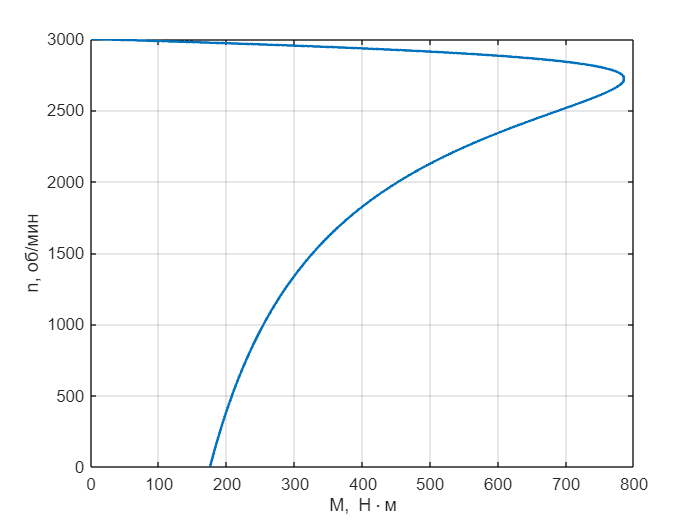

w = 0:0.01:N;
s = (N-w)/N;
n = zeros(1,length(s));
I2 = zeros(1,length(s));
M = zeros(1,length(s));

for i = 1:length(s)
    n(i) = (1-s(i))*n1;
    M(i) = m*zp*Un^2*Rr/w1/s(i)/((Rs+Rr/s(i))^2+(x_s1+x_s2)^2);
end

plot(M,n,'LineWidth',1.5);
% set(gca,'FontSize',16);
hold on;
xlabel('M, Н\cdotм'), ylabel('n, об/мин');
xline(0);
yline(0);
grid on;

% title('M(n)');
M(n == 0)

ans = 175.3266

ks*Mn

ans = 523.8000

lyambda*Mn

ans = 785.7000

Б) Построим семейство механических характеристик при изменении напряжения питания от$\;0\ldotp 1U_n \;$до $U_n$ с шагом $0\ldotp 1U_n$

U_a = 0.1*Un:0.1*Un:Un;

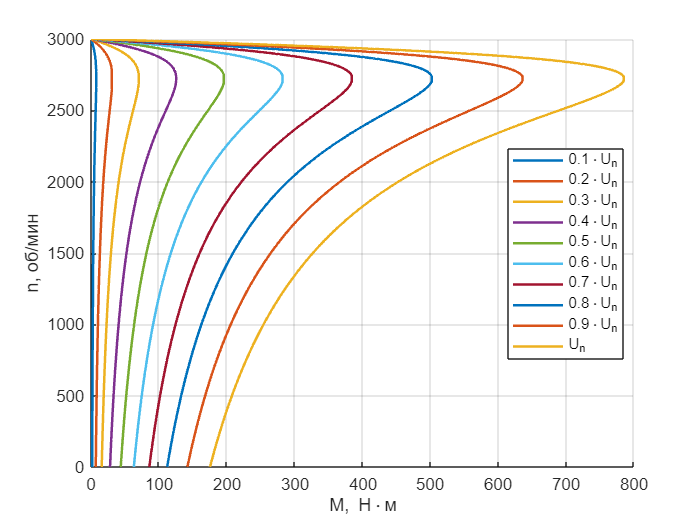

figure();
hold on;
grid on;

for i = 1:length(U_a)
    hold all
    M_a = m*zp*U_a(i)^2*Rr./(w1*s.*((Rs+Rr./s).^2+(x_s1+x_s2)^2));
    plot(M_a,n,'LineWidth',1.5);
end
% xlim([0 25]);
xlabel('M, Н\cdotм'), ylabel('n, об/мин');
% set(gca,'FontSize',16);
legend('0.1\cdotU_n','0.2\cdotU_n','0.3\cdotU_n','0.4\cdotU_n','0.5\cdotU_n','0.6\cdotU_n','0.7\cdotU_n','0.8\cdotU_n','0.9\cdotU_n','U_n', ...
    'Location', 'best');

В) Построим семейство механических характеристик при изменении частоты питания от$\;0\ldotp 1\omega_n \;$до $\omega_n$ с шагом $0\ldotp 1\omega_n$

% Электрическая частота
w0_ = 2*pi*f;
w_ = 0.1*w0_:0.1*w0_:w0_;
% Механическая частота
w_mech0 = 2*pi*f/zp;
w_mech = 0.1*w_mech0:0.1*w_mech0:w_mech0;
% Индуктивность обмоток
L1 = x_s1 / w0_;
L2 = x_s2 / w0_;
Lm = x_m / w0_;
% изменяющиеся индуктивные сопротивления рассеяния 
x_s1 = L1 * w_;
x_s2 = L2 * w_;
x_m = Lm * w_;

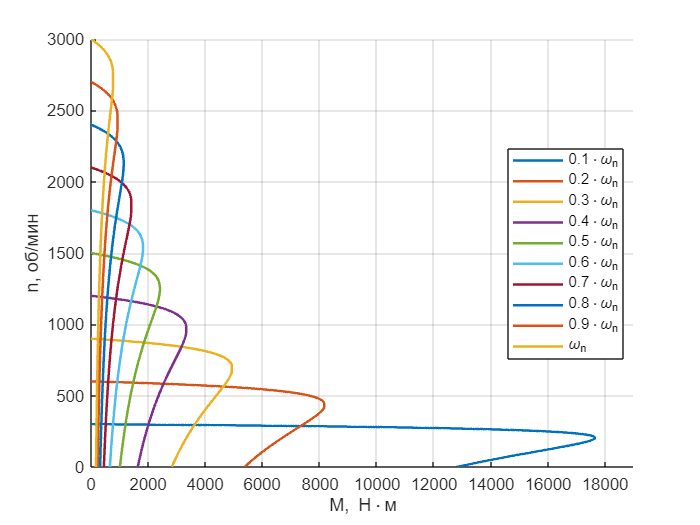

figure();
hold on;
grid on;

for i = 1:length(w_)
    hold all
    n0 = w_mech(i)*30/pi;
    n = 0:0.01:n0;
    s = (n0-n)/n0;
    M_b = m*zp*Un^2*Rr./(w_(i)*s.*((Rs+Rr./s).^2+(x_s1(i)+x_s2(i))^2));
    plot(M_b,n,'LineWidth',1.5);
end
xlabel('M, Н\cdotм'), ylabel('n, об/мин');
% set(gca,'FontSize',16);
legend('0.1\cdot\omega_n','0.2\cdot\omega_n','0.3\cdot\omega_n','0.4\cdot\omega_n','0.5\cdot\omega_n', ...
    '0.6\cdot\omega_n','0.7\cdot\omega_n','0.8\cdot\omega_n','0.9\cdot\omega_n','\omega_n', 'Location','best');
xlim([0 19000])

Г) Построим семейство механических характеристик при скалярном частотном регулировании по закону $\frac{U}{f}=\textrm{const}$ для частот притания от$\;0\ldotp 1\omega_n \;$до $\omega_n$ с шагом $0\ldotp 1\omega_n$

alpha = w_/w0_;
U_g = Un*alpha;

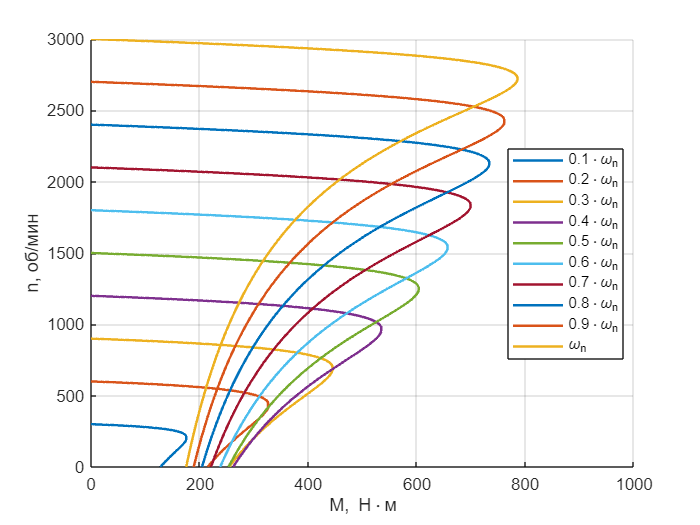

figure();
hold on;
grid on;

for i = 1:length(w_)
    hold all
    n0 = w_mech(i)*30/pi;
    n = 0:0.01:n0;
    s = (n0-n)/n0;
    M_g = m*zp*U_g(i)^2*Rr./(w_(i)*s.*((Rs+Rr./s).^2+(x_s1(i)+x_s2(i))^2));
    plot(M_g,n,'LineWidth',1.5);
end
xlabel('M, Н\cdotм');
ylabel('n, об/мин');
% title('Механическая характеристика при скалярном частотном регулировании','FontSize',24);
% set(gca,'FontSize',16);
legend('0.1\cdot\omega_n','0.2\cdot\omega_n','0.3\cdot\omega_n','0.4\cdot\omega_n','0.5\cdot\omega_n', ...
    '0.6\cdot\omega_n','0.7\cdot\omega_n','0.8\cdot\omega_n','0.9\cdot\omega_n','\omega_n', 'Location', 'best');
xlim([0 1000])

Д) Построим семейство механических характеристик при скалярном частотном регулировании по закону $\frac{U}{f}=\textrm{const}$ с IR компенсацией для частот притания от$\;0\ldotp 1\omega_n \;$до $\omega_n$ с шагом $0\ldotp 1\omega_n$

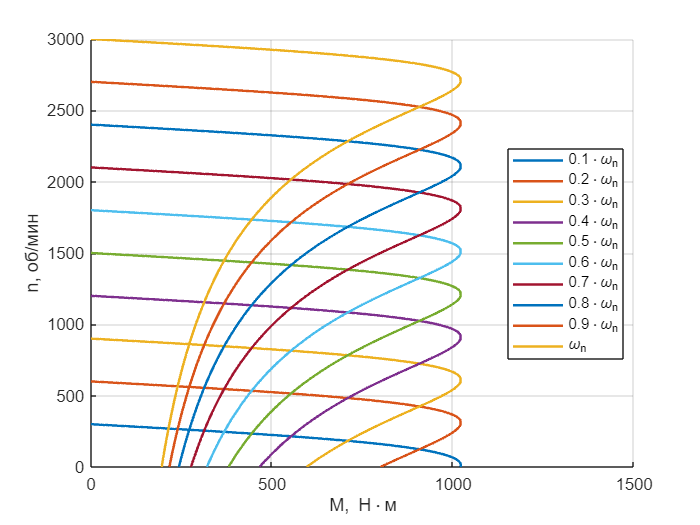

figure();
hold on;
grid on;

I10 = Un/sqrt(Rs^2+(L1*w0_+Lm*w0_)^2);
Uad = (Un - I10*Rs);
U_d = alpha*Uad;

for i = 1:length(w_)
    hold all
    n0 = w_mech(i)*30/pi;
    n = 0:0.01:n0;
    s = (n0-n)/n0;
    M_d = m*zp*U_d(i)^2*Rr./(w_(i).*s.*((Rr./s).^2+(x_s1(i)+x_s2(i))^2));
    plot(M_d,n,'LineWidth',1.5);
end
xlabel('M, Н\cdotм');
ylabel('n, об/мин');
% title('Механическая характеристика при скалярном частотном регулировании и IR компенсации','FontSize',24);
% set(gca,'FontSize',16);
legend('0.1\cdot\omega_n','0.2\cdot\omega_n','0.3\cdot\omega_n','0.4\cdot\omega_n','0.5\cdot\omega_n', ...
    '0.6\cdot\omega_n','0.7\cdot\omega_n','0.8\cdot\omega_n','0.9\cdot\omega_n','\omega_n', 'Location', 'best');
xlim([0 1500])

E) Построим семейство механических характеристик при скалярном частотном регулировании по закону $\frac{U}{f}=\textrm{const}$ с IZ компенсацией для частот притания от$\;0\ldotp 1\omega_n \;$до $\omega_n$ с шагом $0\ldotp 1\omega_n$

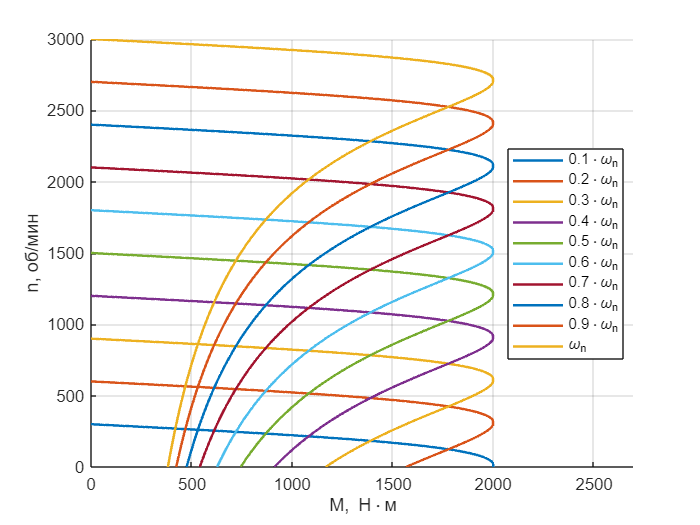

figure();
hold on;
grid on;

Ubd = Un - I10*sqrt(Rs^2+(L1*w0_)^2);
U_e = alpha*Ubd;

for i = 1:length(w_)
    hold all
    n0 = w_mech(i)*30/pi;
    n = 0:0.01:n0;
    s = 2*(n0-n)/n0;
    M_e = m*zp*U_e(i)^2*Rr./(w_(i).*s.*((Rr./s).^2+(x_s2(i))^2));
    plot(M_e,n,'LineWidth',1.5);
end
xlabel('M, Н\cdotм');
ylabel('n, об/мин');
% title('Механическая характеристика при скалярном частотном регулировании и IZ компенсации','FontSize',24);
% set(gca,'FontSize',16);
legend('0.1\cdot\omega_n','0.2\cdot\omega_n','0.3\cdot\omega_n','0.4\cdot\omega_n','0.5\cdot\omega_n', ...
    '0.6\cdot\omega_n','0.7\cdot\omega_n','0.8\cdot\omega_n','0.9\cdot\omega_n','\omega_n', 'Location', 'best');
xlim([0 2700])